orange_data = readtable("data\Vibration - Orange Line\Raw Data.csv","VariableNamingRule","modify");

blue_data = readtable("data\Vibration - Blue Line\Raw Data.csv","VariableNamingRule","modify");

red_data = readtable("data\Vibration - Red Line\Raw Data.csv","VariableNamingRule","modify");

commuter_data = readtable("data\Vibration - Commuter Rail\Raw Data.csv","VariableNamingRule","modify");

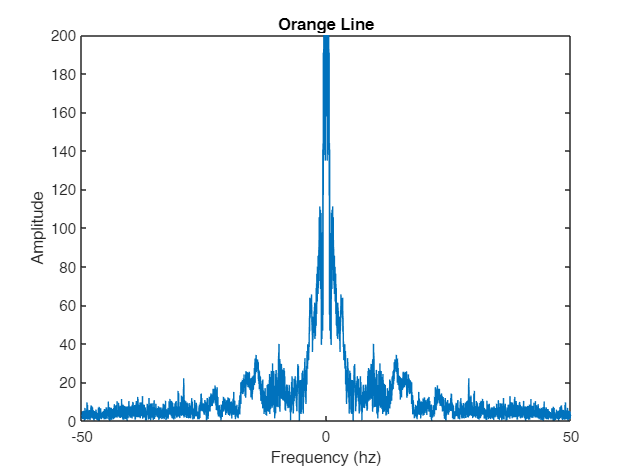

% subplot(2,2,1);
do_fft(orange_data)
title("Orange Line")

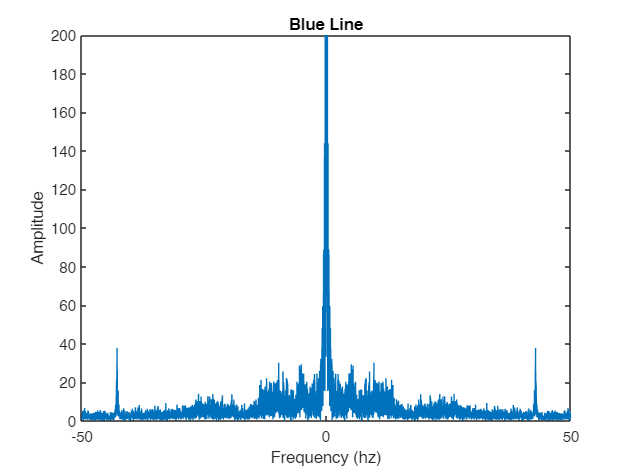


% subplot(2,2,2);
do_fft(blue_data)
title("Blue Line")

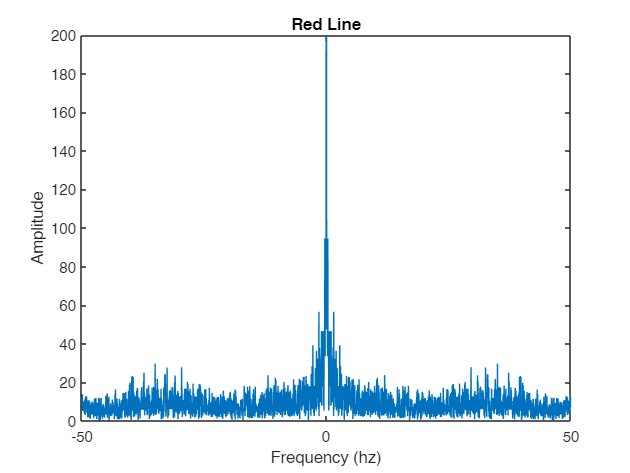


% subplot(2,2,3);
do_fft(red_data)
title("Red Line")

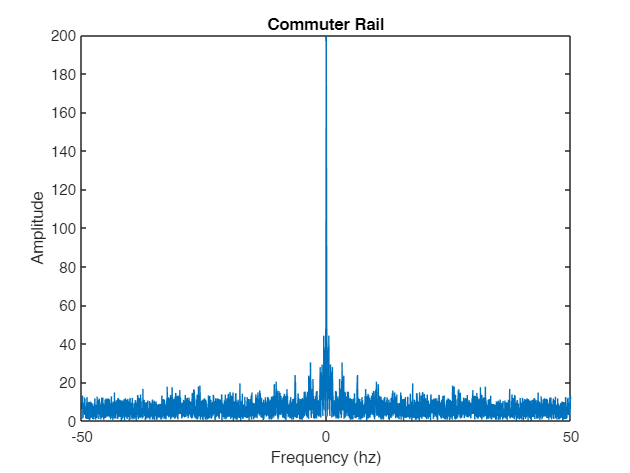


% subplot(2,2,4);
do_fft(commuter_data)
title("Commuter Rail")

function do_fft(data)
    abs_acc = data.AbsoluteAcceleration_m_s_2_;

    Fs = 100;
    N = length(abs_acc);
    low = (-pi + pi/N) * Fs;
    high = (pi - pi/N) * Fs;
    
    fft_data = fft(abs_acc);
    frequencies_shifted = linspace(low, high, N);
    freq_hz = frequencies_shifted / (2 * pi);

%     filter = ones(size(fft_data));
%     filter(fft_data > 600) = 0.01;
%     filtered_data = fft_data .* filter;
    
    plot(freq_hz, fftshift(abs(fft_data)));
%     xlim([-1000 1000])
    ylim([0 200])
    xlabel("Frequency (hz)")
    ylabel("Amplitude")
end